# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

# Tema 5: - Clasificador de Dígitos Usando HOG Features

Este ejemplo muestra cómo clasificar dígitos utilizando características HOG y un clasificador SVM multiclase.

La clasificación de objetos es una tarea importante en muchas aplicaciones de visión por ordenador, incluyendo la vigilancia, la seguridad en el automóvil y la recuperación de imágenes. Independientemente del tipo de objeto que se clasifique, el procedimiento básico para crear un clasificador de objetos es el siguiente

- Adquirir un conjunto de datos etiquetados con imágenes del objeto deseado.

- Dividir el conjunto de datos en un conjunto de entrenamiento y un conjunto de test.

- Entrenar el clasificador utilizando las características extraídas del conjunto de entrenamiento.

- Probar el clasificador utilizando las características extraídas del conjunto de test.

El **objetivo** de este ejercicio es  clasificar dígitos numéricos utilizando características `HOG` (`Histogram of Oriented Gradient`) y un clasificador multiclase `SVM` (`Support Vector Machine`). Este tipo de clasificación se utiliza a menudo en muchas aplicaciones de reconocimiento óptico de caracteres (`OCR`).

**Nota**: El ejemplo utiliza la función `fitcecoc` de la `Statistics and Machine Learning Toolbox™` y la función `extractHOGFeatures` de la `Computer Vision Toolbox™`. (Estas toolbox deberían estar instaladas)

close all;
clear all; 
clc; 
addpath(genpath(pwd));

## (Etapa 1) Base de datos.

Se va a utilizar un conjunto de imágenes de dígitos sintéticos de 16x16 píxeles, que están contenidos en `digits.zip,` (también se puede obtener de `Computer Vision Toolbox™`). 

El conjunto de **entrenamiento** consta de 101 imágenes para cada uno de los 10 dígitos (**1010** imágenes). Cada una de las imágenes de entrenamiento contiene un dígito rodeado de otros dígitos, lo que imita cómo se ven normalmente los dígitos juntos. 

Aunque no es el conjunto de datos más representativo, hay suficientes datos para entrenar y probar un clasificador, y mostrar la viabilidad del enfoque.

**Se Pide:**

- Muestre 3 imágenes del conjunto de entrenamiento tomadas de forma aleatoria (puede utilizar la función [randi](https://es.mathworks.com/help/matlab/ref/double.randi.html) para obtener número enteros de forma aleatoria).

% Datos para TRAIN
% (opción a) a partir de Computer Vision Toolbox™
% trainingSet_path = fullfile(toolboxdir('vision'),'visiondata','digits','synthetic');
% (opción b) a partir del fichero digits.zip
trainingSet_path = 'digits/synthetic/';


% imageDatastore crea una "lista" con todas las imágenes de esa carpeta. No las carga todas en memoria, solo apunta a dónde están.
% 'LabelSource','foldernames' hace que la etiqueta de cada imagen sea el nombre de su carpeta. Así, las imágenes de la carpeta 3 quedan etiquetadas como "3".
% countEachLabel muestra cuántas imágenes hay de cada número.
trainingSet = imageDatastore(trainingSet_path,'IncludeSubfolders',true,'LabelSource','foldernames');
countEachLabel(trainingSet)

ans = 10×2 table
    Label    Count
    _____    _____

      0       101 
      1       101 
      2       101 
      3       101 
      4       101 
      5       101 
      6       101 
      7       101 
      8       101 
      9       101 

	Get insights using Copilot


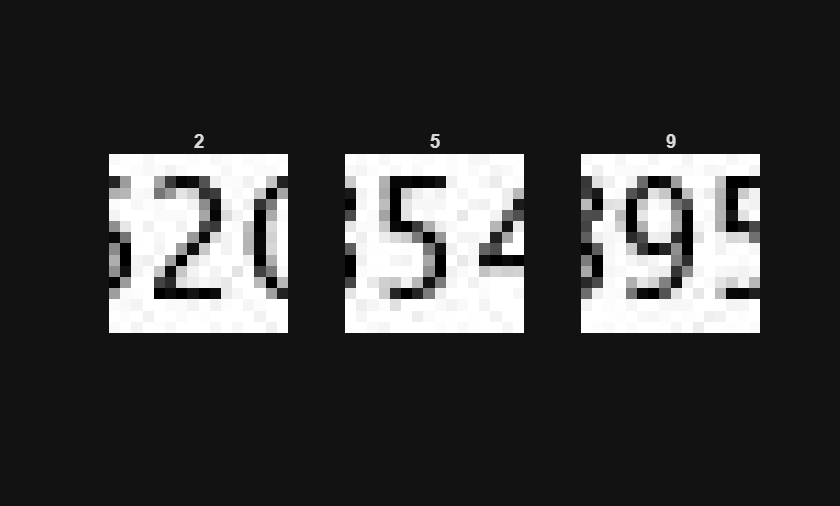


% COMPLETE el codigo para:
% mostrar 3 imágenes de entrenamiento tomadas de forma aleatoria
figure;
for i=1:3
    subplot(1,3,i);
    random_num = randi(numel(trainingSet.Files));    % número al azar entre 1 y 1010
    img = readimage(trainingSet, random_num);         % lee esa imagen
    imshow(img);                                      % la muestra
    title(string(trainingSet.Labels(random_num)));    % pone su etiqueta encima
end

## (Etapa 2) **Extracción de características**.

Los datos utilizados para entrenar el clasificador son vectores de características HOG extraídos de las imágenes de entrenamiento y que se pueden obtener con la función [`extractHOGFeatures`](https://es.mathworks.com/help/vision/ref/extracthogfeatures.html?searchHighlight=extractHOGFeatures&s_tid=srchtitle_support_results_1_extractHOGFeatures). 

HOG por defecto utiliza por defecto un tamaño de celda (`CellSize``)de` `[8 8]` y construye histogramas de `9 bins` a apartir de la imagen gradiente. Después contruye bloques de `16×16` (4 histogramas) y forma un vector de `36×1` elementos, que son normalizados. Este proceso lo repite haciendo 7 desplazamientos horizontales y 15 verticales de los bloques de `16×16`, lo que hace un total de 105 bloques de vectores de `36×1` elementos, luego la dimensión del vector final es `36x105=``3780`` elementos`.

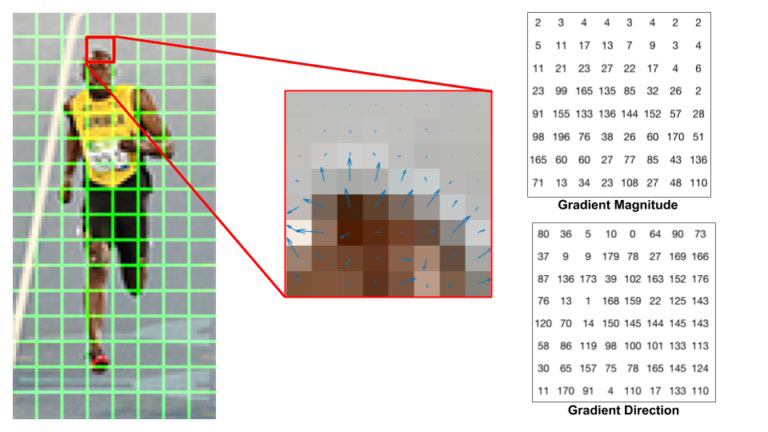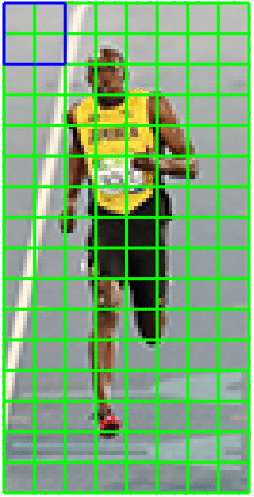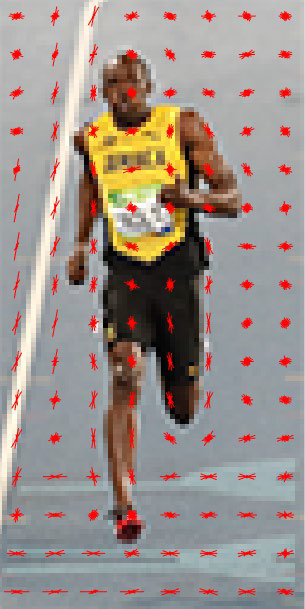

La función [`extractHOGFeatures`](https://es.mathworks.com/help/vision/ref/extracthogfeatures.html?searchHighlight=extractHOGFeatures&s_tid=srchtitle_support_results_1_extractHOGFeatures) puede devolver el resultado de visualización. Variando el parámetro del tamaño de la celda HOG (CellSize`)` y visualizando el resultado, se puede ver el efecto que tiene el parámetro del tamaño de la celda en la cantidad de información codificada en el vector de características

Explicación de que es HOG:

La SVM no sabe "mirar" una imagen. Necesita una lista de números que describa cada imagen. HOG sirve para fabricar esa lista, y se fija en la forma del número, es decir, en sus bordes:

- Busca los bordes: los sitios donde la imagen pasa de oscuro a claro. Para cada píxel calcula hacia qué dirección va ese cambio (horizontal, vertical, diagonal...). Eso es el gradiente.

- Divide la imagen en celdas: cuadraditos de, por ejemplo, 4x4 píxeles.

- En cada celda hace un recuento de cuántos bordes van en cada dirección. Usa 9 direcciones posibles, que son los 9 bins del histograma. Ese recuento es el "histograma de gradientes orientados" que da nombre a HOG (Histogram of Oriented Gradients):

-             C`aja 1:   0° a  20°   ─   (casi horizontal)`

-             `Caja 2:  20° a  40°`

-             `Caja 3:  40° a  60°   ╱   (diagonal)`

-             `Caja 4:  60° a  80°`

-             `Caja 5:  80° a 100°   │   (casi vertical)`

-             `Caja 6: 100° a 120°`

-             `Caja 7: 120° a 140°   ╲   (la otra diagonal)`

-             `Caja 8: 140° a 160°`

-             `Caja 9: 160° a 180°   ─   (casi horizontal otra vez)`

      Se reparten 180° en 9 cajas de 20° cada una. Se usan 180° y no 360° porque una línea que sube y una que baja son la misma línea

            En cada cuadradito, cada píxel de borde vota por su dirección (una de 9 cajas). Eso es el histograma: 9 números.

        4. Junta todos los recuentos en una sola lista larga: el vector de características.

Por ejemplo, un "1" tiene sobre todo bordes verticales y un "0" tiene bordes en todas direcciones formando un círculo. Por eso sus listas salen distintas y la SVM puede diferenciarlos.

**Se pide:**

- Uno de los parámetros que hay que cambiar es el tamaño de celda (`CellSize``)`, por defecto es `[8 8]`, dado que las imágenes son de 16x16 píxeles este tamaño codifica insuficiente información, por lo que debe cambiar el tamaño a [4 4] y luego a [2 2], visualizar en ambos casos el resultado para la imagen 1 y elijir uno de los dos valores utilizados para continuar con la práctica.

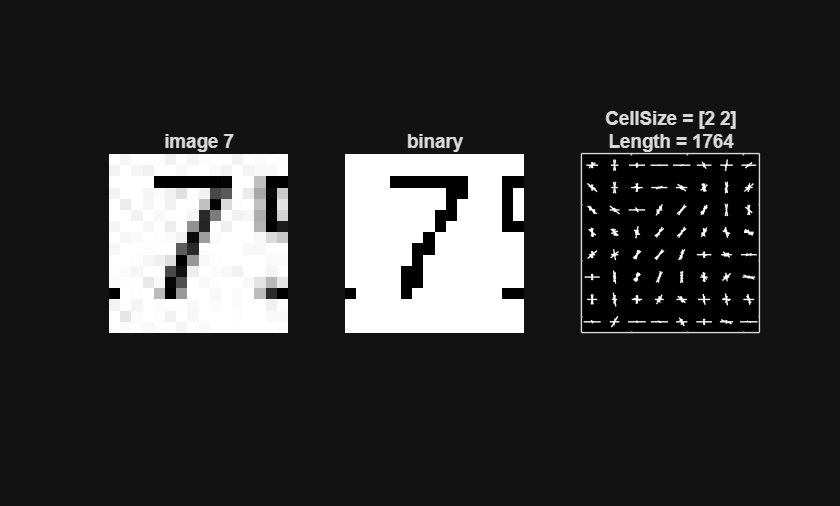

% (a) Cálculo del tamaño del vector de características de HOG

% se lee la primera imagen del dataset de train
image_num = 758;
img = readimage(trainingSet,image_num);

% tamaño de la celda HOG. En cuadraditos de qué tamaño se corta la imagen 
% Cada estrella resume un cuadradito. Sus rayitas dicen en qué dirección van los bordes del número en ese trozo
% Cada estrella son 9 números, uno por cada una de las 9 direcciones posibles. 
% HOG junta todas las estrellas en una lista, y esa lista es la que "ve" la SVM.
CellSize = [2 2]; % RELLENAR AQUí!!!

% valores por defecto de extractHOGFeatures
BlockSize = [2 2];
BlockOverlap = ceil(BlockSize/2);
NumBins = 9;
BlocksPerImage = floor((size(img(:,:,1))./CellSize - BlockSize)./(BlockSize - BlockOverlap) + 1);
% tamaño del vector de características de HOG
hogFeatureSize = prod([BlocksPerImage, BlockSize, NumBins]);

% extracción del vector de caracterísitcas de HOG
[hog_vect, hog_vis] = extractHOGFeatures(img,'CellSize',CellSize);

% visualización del vector de caracterísitcas de HOG
figure; 
subplot(1,3,1);
imshow(img);
title(['image ' char(trainingSet.Labels(image_num))])
grey = im2gray(img);
% Apply pre-processing steps
bw = imbinarize(grey);
subplot(1,3,2);
imshow(bw);
title('binary')
% Visualize the HOG features
subplot(1,3,3);  
plot(hog_vis); 
title(sprintf('CellSize = [%d %d]\nLength = %d',CellSize(1,1),CellSize(1,2),hogFeatureSize));

**Se pide:**

- Complete el bucle que extrae las características HOG de cada imagen del conjunto de entranmiento con la función [`extractHOGFeatures`](https://es.mathworks.com/help/vision/ref/extracthogfeatures.html?searchHighlight=extractHOGFeatures&s_tid=srchtitle_support_results_1_extractHOGFeatures), asegurándose de que utilice el tamaño de celda `CellSize`, y guarde los vectores en la variable llamada `trainingFeatures`. 

% (b) Extracción de caracterísitcas para el conjunto de datos de TRAIN

% Se calcula el número de elementos de la matriz con 'numel'
numImagesTrain = numel(trainingSet.Files);
trainingFeatures = zeros(numImagesTrain,hogFeatureSize,'single');

% Ahora se repite lo mismo para las 1010 imágenes de entrenamiento y se guarda cada lista en una fila de trainingFeatures
for i = 1:numImagesTrain
    % se lee cada imagen
    img = readimage(trainingSet, i);
    % se extrae el descriptor HOG y se guarda
    trainingFeatures(i, :) = extractHOGFeatures(img, 'CellSize', CellSize);
end

% se obtienen las etiquetas para cada imagen.
trainingLabels = trainingSet.Labels;


## (Etapa 3) Entrenamiento

El entrenamiento del clasificador de dígitos se realiza con la función [fitcecoc](https://www.mathworks.com/help/stats/fitcecoc.html), que ajustar modelos multiclase para máquinas de vectores soporte (SVM) u otros clasificadores. Los datos para entrenar son las características HOG extraídas del conjunto de entrenamiento. Se puede configurar el esquema de codificación multiclase como `'one-vs-one' `ó `'one-vs-all'`.

**Se pide:**

- Rellene la función [fitcecoc](https://www.mathworks.com/help/stats/fitcecoc.html) para que realice el entrenamiento, utilizando una codificación ('`Coding'`) 'One-vs-One' para crear el clasificador multiclase utilizando SVMs binarias. El modelo del clasificador se guardará en la variable llamada **MdlClassifier**`.`

**Nota**: para utilizar la función [`fitcecoc`](https://es.mathworks.com/help/stats/fitcecoc.html?searchHighlight=fitcecoc&s_tid=srchtitle_support_results_1_fitcecoc) hay que tener instlada la Toolbox™ `Statistics and Machine Learning`.

% fitcecoc uses SVM learners and a 'One-vs-One' encoding scheme.

% COMPLETAR AQUÍ!!!!
% fitcecoc usa SVM por defecto
% trainingFeatures: las listas HOG de las 1010 imágenes (lo de la Etapa 2).
% trainingLabels: qué número es cada imagen (las respuestas correctas).
% onevsone o onevsall ----------------------------
% ver en cmd MdlClassifier
MdlClassifier = fitcecoc(trainingFeatures, trainingLabels, 'Coding', 'onevsone');

## (Etapa 4) Predicción

Se obtienen las predicciones del modelo entrenado para todas las imágenes de test con la función [predict](https://es.mathworks.com/help/stats/classificationecoc.predict.html).

El conjunto de **test** consta de 12 imágenes por dígito (**120** imágenes). Para las pruebas, se utilizan escaneos de dígitos escritos a mano para validar el rendimiento del clasificador con datos diferentes a los de entrenamiento. 

**Se pide:**

- Cargue el conjunto de datos de **test **(`'digits/handwritten/'`), al igual que ha realizado en la etapa 1.

- Extraiga las características HOG para este conjunto de datos, del mismo modo se ha realizado en la etapa 2 (¡OJO! debe tener el mismo tamaño de celda **CellSize**, por lo que debe haber ejecutado previamente la Etapa 2).

- Por último, obtenga las predicciones para cada una de las imagenes de test con la función [predict](https://es.mathworks.com/help/stats/classificationecoc.predict.html) y guardelas en la variable llamada `predictedLabels`.

% Completar todo

% Datos para TEST. Igual que en la Etapa 1, pero con la carpeta handwritten
testSet = imageDatastore('digits/handwritten/', 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
countEachLabel(testSet)

ans = 10×2 table
    Label    Count
    _____    _____

      0       12  
      1       12  
      2       12  
      3       12  
      4       12  
      5       12  
      6       12  
      7       12  
      8       12  
      9       12  

	Get insights using Copilot


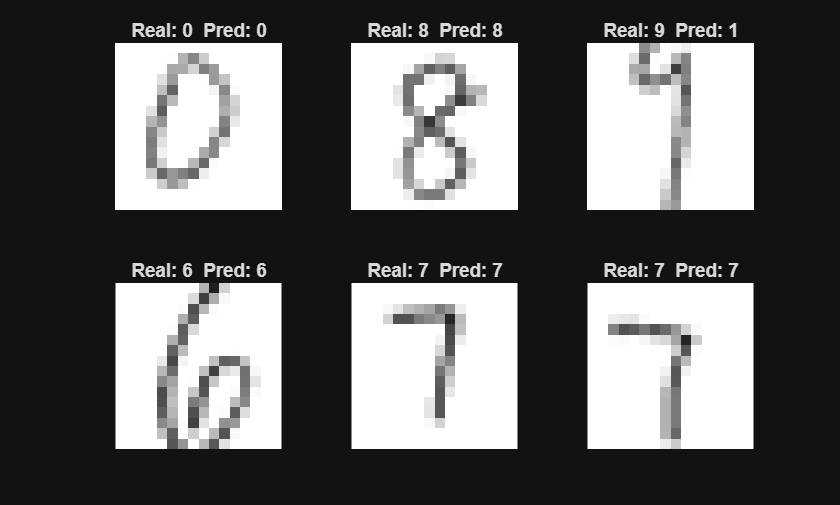


% Extracción de características HOG del conjunto de TEST (igual que en la Etapa 2), cambiando trainingSet por testSet
numImagesTest = numel(testSet.Files);
testFeatures = zeros(numImagesTest, hogFeatureSize, 'single');

for i = 1:numImagesTest
    img = readimage(testSet, i);
    testFeatures(i, :) = extractHOGFeatures(img, 'CellSize', CellSize); %mismo CellSize
end

% Etiquetas reales de las imágenes de test
% guarda las respuestas correctas. El modelo no las ve; son para comprobar los aciertos en la Etapa 5.
testLabels = testSet.Labels;

% Predicciones de clase utilizando las características HOG de las imagenes de test.
predictedLabels = predict(MdlClassifier, testFeatures);

%extra: prints ejemplo 
figure;
for i = 1:6
    subplot(2,3,i);
    n = randi(numImagesTest);
    imshow(readimage(testSet, n));
    title(sprintf('Real: %s  Pred: %s', char(testLabels(n)), char(predictedLabels(n))));
end

## (Etapa 5) Resultados

Se debe evaluar el clasificador utilizando los resultados obtenidos para el conjunto de test, generando la matriz de confusión y calculando a partir de ésta  parámetros como: `Accuracy, Macro_Recall, Macro_Precision y Macro_F1_score`.

**Se pide:**

- Calcule la matriz de confusión con la función [confusionmat](https://es.mathworks.com/help/stats/confusionmat.html) o [confusionchart](https://es.mathworks.com/help/releases/R2025a/deeplearning/ref/confusionchart.html) y guarde el resultado en una variable llamada `CM`. 

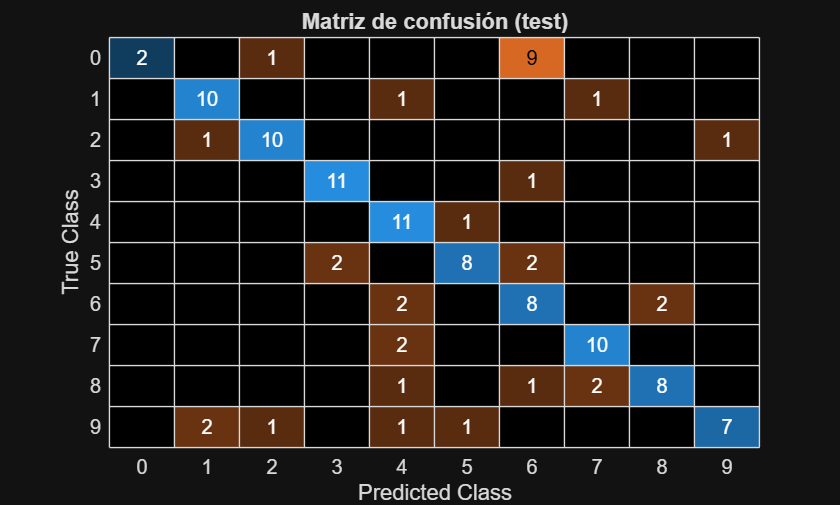

% Matriz de Confusión
% COMPLETAR AQUÍ!!!

CM = confusionmat(testLabels, predictedLabels);

figure
confusionchart(testLabels, predictedLabels);
title('Matriz de confusión (test)');


% Accuracy: aciertos / total (% aciertos)
Accuracy = sum(diag(CM)) / sum(CM(:))

Accuracy = 0.7083

**Se pide:**

- Codifique una función llamada `multiclass_scores` a la que se le pase la matriz de confusión `CM` y devuelva dos arrays: el primero llamado `ClassScores` de tamaño *Mx3*, donde *M* es el número filas que se corresponde con el número de clase (en este caso 10 clases, una para cada dígito) y tres columnas en las que está el cálculo de: `Recall, Precision` y `F1_Score` para cada una de las clases. El segundo array llamado MacroScores es de tamaño 1x3 y contiene los siguientes valores:` Macro_Recall, Macro_Precision y Macro_F1_Score`.

% Scores
[ClassScores, MacroScores] = multiclass_scores(CM);

labels = categories(categorical(0:1:9));
CScores = array2table(ClassScores,'RowNames',labels,'VariableNames',{'Recall','Precision','F1_Score'})

CScores = 10×3 table
         Recall     Precision    F1_Score
         _______    _________    ________

    0    0.16667           1     0.28571 
    1    0.83333     0.76923         0.8 
    2    0.83333     0.83333     0.83333 
    3    0.91667     0.84615        0.88 
    4    0.91667     0.61111     0.73333 
    5    0.66667         0.8     0.72727 
    6    0.66667     0.38095     0.48485 
    7    0.83333     0.76923         0.8 
    8    0.66667         0.8     0.72727 
    9    0.58333       0.875         0.7 

	Get insights using Copilot


GScores = array2table(MacroScores,'RowNames',{'Global'},'VariableNames',{'Macro-Recall', 'Macro-Precision','Macro-F1'})

GScores = 1×3 table
              Macro-Recall    Macro-Precision    Macro-F1
              ____________    _______________    ________

    Global      0.70833           0.7685         0.69718 

	Get insights using Copilot


## **MNIST**

**Se pide:**

- Vuelva entrenar el clasificador (completando todos los pasos anteriores) con un conjunto de datos más representativo, el dataset de MNIST, que contiene un conjunto de entrenamiento de 60.000 imágenes de caracteres escritos a mano ('`train-images.idx3-ubyte'`) y sus respectivas etiquetas ('`train-labels.idx1-ubyte'`), y un conjunto de test de 10.000 imágenes ('`t10k-images.idx3-ubyte'`), y sus respectivas etiquetas ('`t10k-labels.idx1-ubyte`'). Para leer estos datos se proporciona la función `readMNIST` cuyos parámetros se explican en la cabecera de la propia función. Un ejemplo de uso sería la siguiente instrucción que lee las 100 primeras imágenes y sus correspondientes etiquetas del  conjunto de datos de test.

`               [imgs labels] = readMNIST('t10k-images.idx3-ubyte', 't10k-labels.idx1-ubyte', 100, 0)`

    **Nota**: esta función carga en un dos arrays,` imgs y labels`, todas las imágenes y sus respectivas etiquetas.

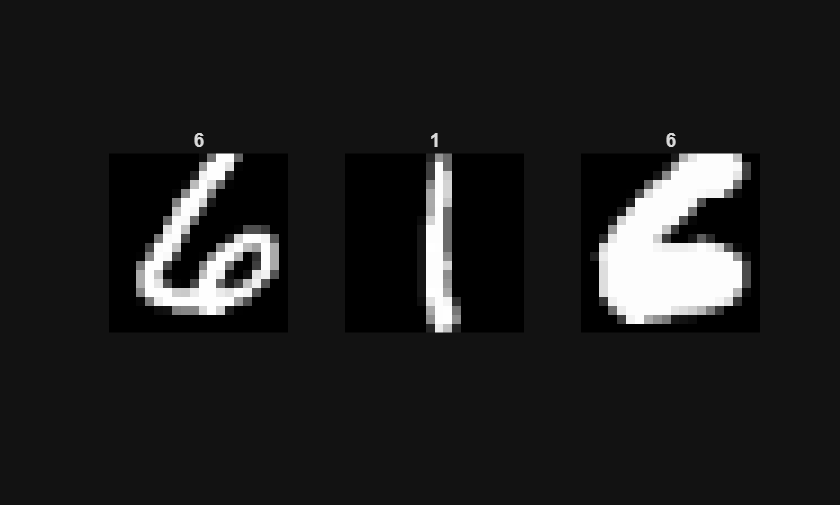

%% MNIST-- hacer TODO.

% Número de imágenes a usar (si tarda mucho, prueba primero con numTrain = 10000)
numTrain = 60000;
numTest  = 10000;

% --- Etapa 1: cargar los datos ---
[imgsTrain, labelsTrain] = readMNIST('train-images.idx3-ubyte', 'train-labels.idx1-ubyte', numTrain, 0);
[imgsTest,  labelsTest]  = readMNIST('t10k-images.idx3-ubyte',  't10k-labels.idx1-ubyte',  numTest,  0);

% Las etiquetas vienen como números -> se pasan a categorías (como en el resto de la práctica)
labelsTrain = categorical(labelsTrain);
labelsTest  = categorical(labelsTest);

% Mostrar 3 imágenes al azar
figure;
for i = 1:3
    subplot(1,3,i);
    n = randi(numTrain);
    imshow(imgsTrain(:,:,n));
    title(char(labelsTrain(n)));
end

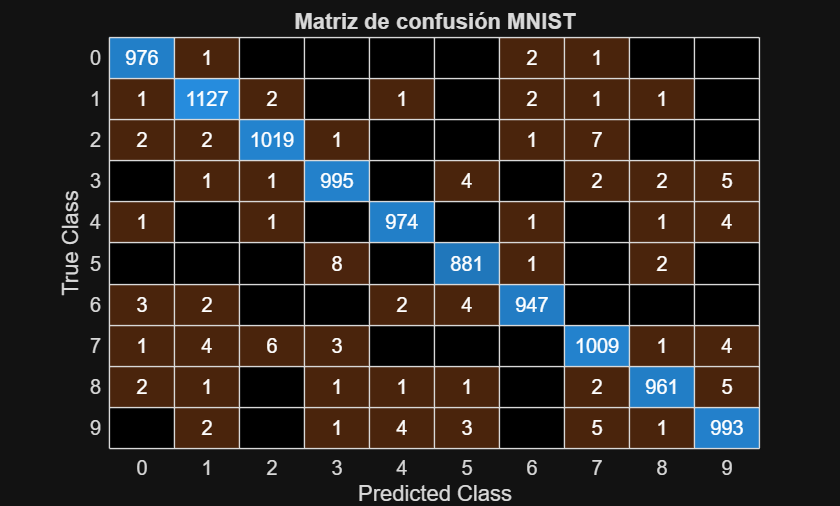


% --- Etapa 2: extraer HOG ---
CellSize = [4 4];

% longitud del vector HOG (se calcula con la primera imagen)
hogSizeMNIST = numel(extractHOGFeatures(imgsTrain(:,:,1), 'CellSize', CellSize));

trainFeaturesMNIST = zeros(numTrain, hogSizeMNIST, 'single');
for i = 1:numTrain
    trainFeaturesMNIST(i,:) = extractHOGFeatures(imgsTrain(:,:,i), 'CellSize', CellSize);
end

testFeaturesMNIST = zeros(numTest, hogSizeMNIST, 'single');
for i = 1:numTest
    testFeaturesMNIST(i,:) = extractHOGFeatures(imgsTest(:,:,i), 'CellSize', CellSize);
end

% --- Etapa 3: entrenar ---
MdlMNIST = fitcecoc(trainFeaturesMNIST, labelsTrain, 'Coding', 'onevsone');

% --- Etapa 4: predecir ---
predictedMNIST = predict(MdlMNIST, testFeaturesMNIST);

% --- Etapa 5: resultados ---
CM_MNIST = confusionmat(labelsTest, predictedMNIST);

figure;
confusionchart(labelsTest, predictedMNIST);
title('Matriz de confusión MNIST');


Accuracy_MNIST = sum(diag(CM_MNIST)) / sum(CM_MNIST(:))

Accuracy_MNIST = 0.9882


[ClassScores_MNIST, MacroScores_MNIST] = multiclass_scores(CM_MNIST);
CScores_MNIST = array2table(ClassScores_MNIST, 'RowNames', labels, 'VariableNames', {'Recall','Precision','F1_Score'})

CScores_MNIST = 10×3 table
         Recall     Precision    F1_Score
         _______    _________    ________

    0    0.99592     0.98986     0.99288 
    1    0.99295      0.9886     0.99077 
    2     0.9874     0.99028     0.98884 
    3    0.98515     0.98612     0.98564 
    4    0.99185     0.99185     0.99185 
    5    0.98767     0.98656     0.98711 
    6    0.98852     0.99266     0.99059 
    7    0.98152     0.98247       0.982 
    8    0.98665     0.99174     0.98919 
    9    0.98414      0.9822     0.98317 

	Get insights using Copilot


GScores_MNIST = array2table(MacroScores_MNIST, 'RowNames', {'Global'}, 'VariableNames', {'Macro-Recall','Macro-Precision','Macro-F1'})

GScores_MNIST = 1×3 table
              Macro-Recall    Macro-Precision    Macro-F1
              ____________    _______________    ________

    Global      0.98818           0.98824         0.9882 

	Get insights using Copilot


# FUNCIONES

function [ClassScores, GlobalScores] = multiclass_scores(CM)

    Recall = [];
    Precision = [];
    F1_Score = [];
    for i=1 : size(CM,1)
        % COMPLETAR AQUÍ!!!!:
        % aciertos de la clase i / total de imágenes que SON de la clase i (su fila)
        Recall(i) = CM(i,i) / sum(CM(i,:));
        % aciertos de la clase i / total de veces que el modelo DIJO la clase i (su columna)
        Precision(i) = CM(i,i) / sum(CM(:,i));
        % media entre las dos
        F1_Score(i) = 2 * Precision(i) * Recall(i) / (Precision(i) + Recall(i));
    end

    ClassScores = [Recall' Precision' F1_Score'];
      
    % COMPLETAR AQUÍ!!!!:
     % Macro = la media de las 10 clases
    Macro_Recall = mean(Recall);
    Macro_Precision = mean(Precision);
    Macro_F1 = mean(F1_Score);

    GlobalScores = [Macro_Recall Macro_Precision Macro_F1];
end
